# Chapter 4, Section 6 (Part 1)

The goal of this activity is to show some graphics operations in $\mathbb R^2$. Let's begin by drawing an image with Matlab's patch(x,y,'color') command. We want to sketch the triangle having vertices at the points (0,1), (2,1), and (1,3). Note that the x-values are 0, 2, and 1.

x=[0 2 1];

Note that the y-values are 1, 1, and 3.

y=[1 1 3];

Now we can use the patch command to draw the triangle.

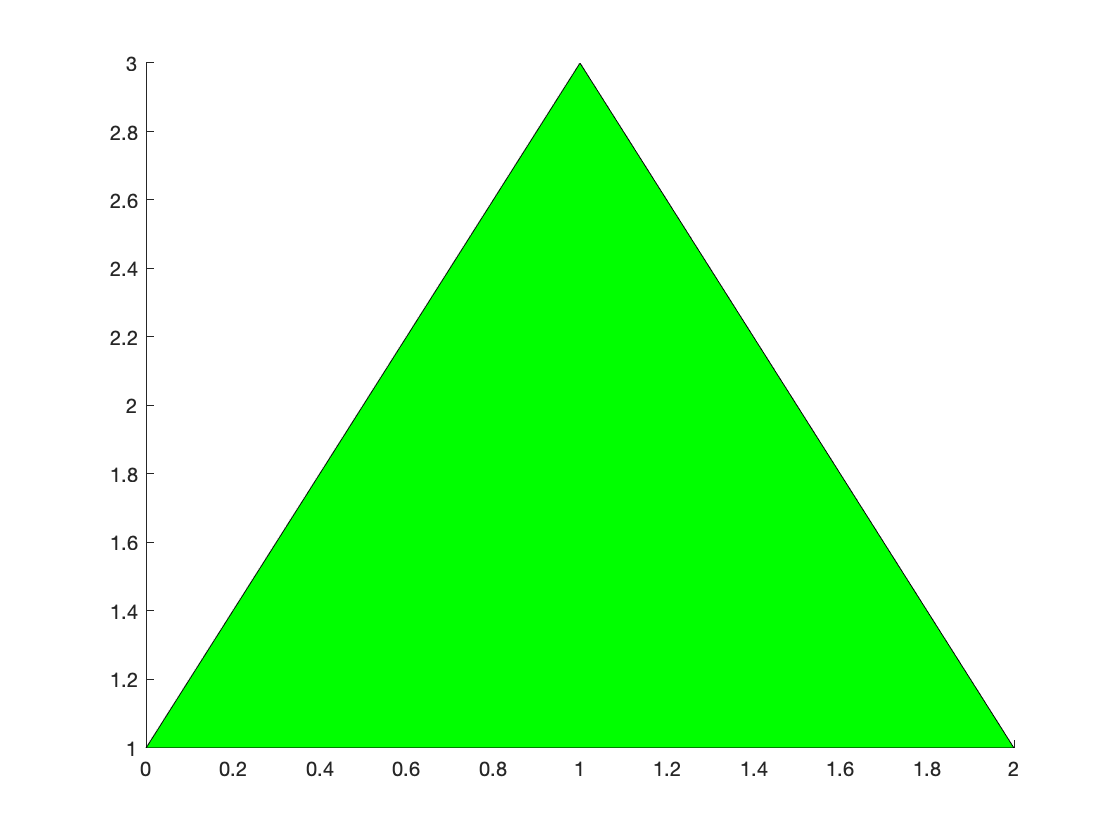

figure
patch(x,y,'g')

Now we will prettify our image a bit. The axis([-5,5,-5,5]) command sets the x-axis from -5 to 5 and the y-axis from -5 to 5. The command gca means "get current axis." If you remove the semicolon, the handle will appear in the command window and you can view all the properties of the current axis that you can play with. We store what is known as a handle to the current axis in the variable ax. Then we set the axis locations to go through the origin for both the x-axis and the y-axis.

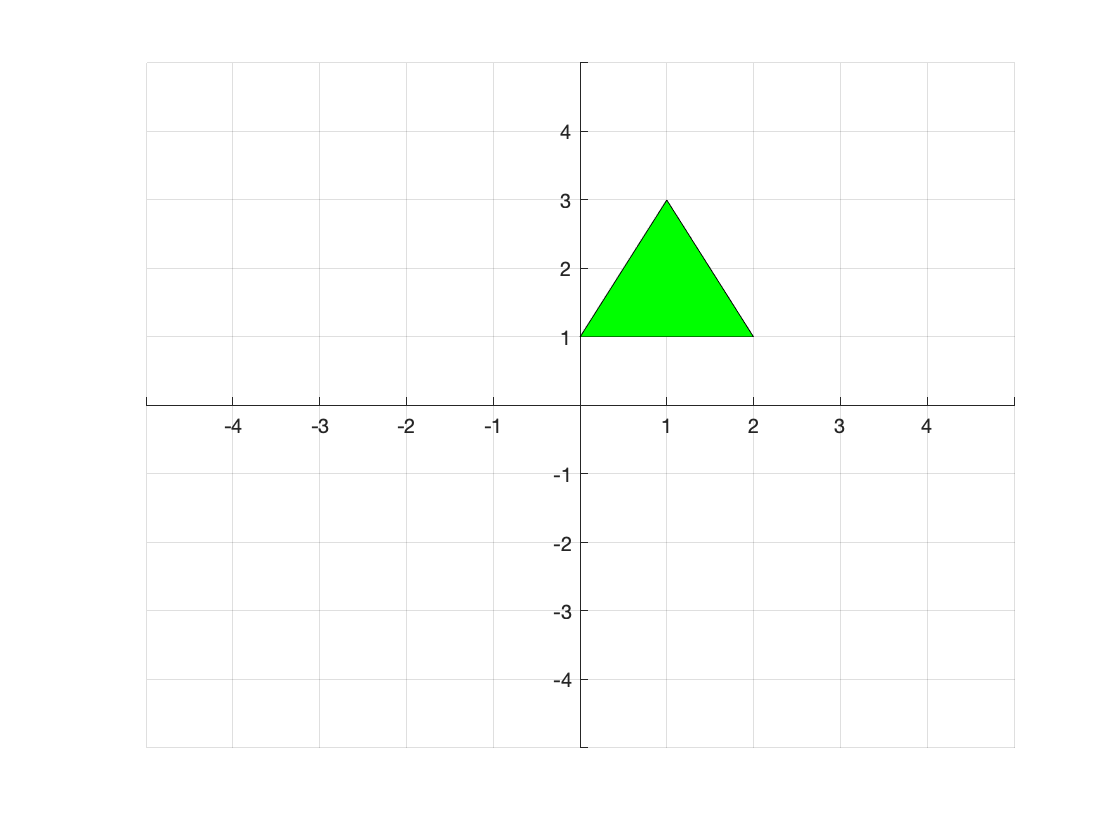

figure
x=[0 2 1];
y=[1 1 3];
patch(x,y,'g')
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Ah! Pretty. Now we will show how to apply some linear tranformations to this image. 

# Example #1

Let's suppose that we would like to double all of the x-values. Then, the linear transformation


$$S=\left(\pmatrix{x\cr y}\right)=\pmatrix{2x\cr y}$$


should perform the task. Note that $S:\mathbb R^2\rightarrow \mathbb R^2$ is a linear transformation. If we use the standard basis for $\mathbb R^2$, that is


$$B=\left\{\pmatrix{1\cr 0},\ \pmatrix{0\cr 1}\right\}$$


then


$$S\left(\pmatrix{1\cr 0}\right)=\pmatrix{2\cr 0}\qquad\text{and}\qquad S\left(\pmatrix{0\cr 1}\right)=\pmatrix{0\cr 1}
$$


so


$$[S]_B=\pmatrix{2 & 0\cr 0 & 1}$$


Now, if we apply this to each of our vertices, here are our results.


$$\begin{array}{rcl}
[S]_B\pmatrix{0\cr 1}&=&\pmatrix{2 & 0\cr 0 & 1}\pmatrix{0\cr 1}=\pmatrix{0\cr 1}\\
[S]_B\pmatrix{2\cr 1}&=&\pmatrix{2 & 0\cr 0 & 1}\pmatrix{2\cr 1}=\pmatrix{4\cr 1}\\
[S]_B\pmatrix{1\cr 3}&=&\pmatrix{2 & 0\cr 0 & 1}\pmatrix{1\cr 3}=\pmatrix{2\cr 3}
\end{array}$$


Note that our matrix doubled each x-value while leaving the y-value alone. It did just as we expected, doubling the x-values. Now, can we do this quickly in Matlab? The answer is "Yes." Again, our x and y values are:

x=[0 2 1];
y=[1 1 3];

Let's combine them in a matrix. Note that we put the x-values in the first row and the y-values in the second row of our matrix, storing the results in the variable pts (you can choose whatever variable name you wish).

pts=[x;y]

pts =      0     2     1
     1     1     3


If we look at the first column, we see the point (0,1), the second column is the point (2,1), and the third column is the point (1,3). Now, recall that one way to multiply matrix $A$ times matrix $B$ is to multiply matrix $A$ times each column of matrix $B$.


$$AB=\pmatrix{A\vec b_1 & A\vec b_2 & \cdots & A\vec b_n}$$


So, if we multiply our matrix $[S]_B$ times our pts matrix, then we multiply matrix $[S]_B$ times each column of our pts matrix. This means that we are applying our matrix $[S]_B$ to each point (vertex) of our triangle. Enter $[S]_B$.

S=[2 0;0 1]

S =      2     0
     0     1


Now, multiply S times pts. We store the results in the variable Spts for later use.

Spts=S*pts

Spts =      0     4     2
     1     1     3


Note that this worked. It doubled each of the x-values (in row one) and left the y-values (in row two) alone. Now, how can we plot these results? The patch(x,y,'color') wants us to enter the vector of x-values, then the vector of y-values, and the color we want. Now, the transformed x-values are stored in the first row of Spts. The command Spts(1,:) means "row one, every column."

Spts(1,:)

ans =      0     4     2


And the y-values are stored in the second row.

Spts(2,:)

ans =      1     1     3


So here is how we will plot our transformation.

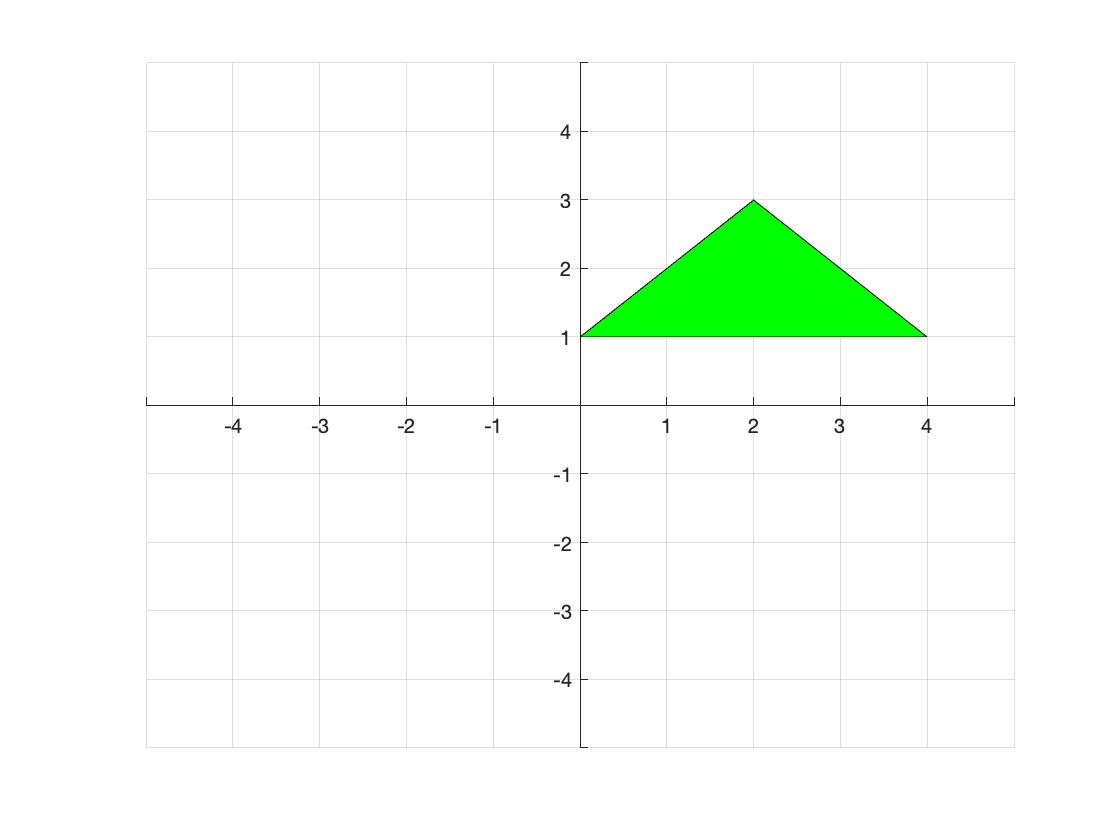

figure
patch(Spts(1,:),Spts(2,:),'g')
axis([-5,5,-5,5])
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

We can easily compare these images by using the subplot command. Here is the complete code for this example.

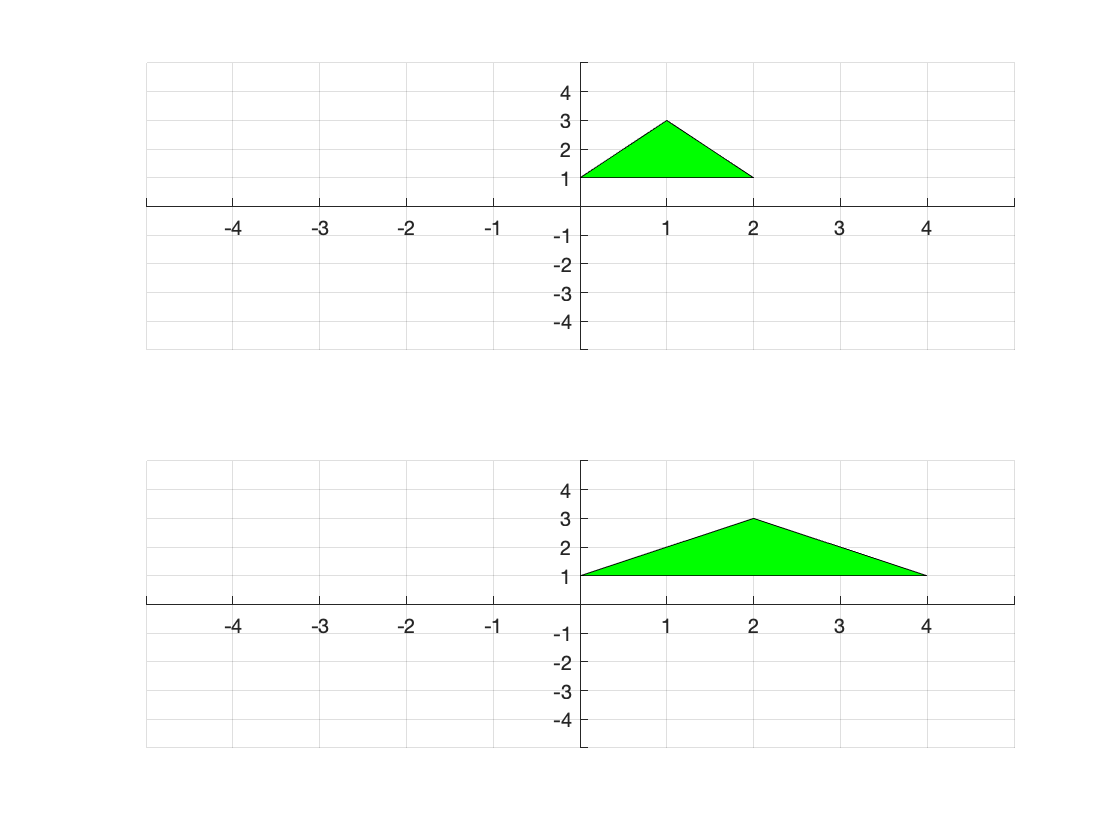

figure
x=[0 2 1];
y=[1 1 3];
subplot(2,1,1)
patch(x,y,'g')
axis([-5,5,-5,5])
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
S=[2 0;0 1];
pts=[x;y];
Spts=S*pts;
subplot(2,1,2)
patch(Spts(1,:),Spts(2,:),'g')
axis([-5,5,-5,5])
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

This is clear visual evidence that we have done this correctly. Note that all the x-values of the vertices of the first triangle have be doubled in the second figure, while the y-values have remained the same. This is called a "dilation."

# Example #2

Contract the given triangle in Example #1 by a factor of 3.

**Solution: **What this means is that we want to multiply all of our y-values by 1/3.


$$S\left(\pmatrix{x\cr y}\right)=\pmatrix{x\cr (1/3)y}$$


Now, inserting the standard basis vectors for $\mathbb R^2$, that is, $[S]_B=\pmatrix{S(\vec e_1) & S(\vec e_2)}$, gives us:


$$[S]_B=\pmatrix{1 & 0\cr 0 & 1/3}$$


Now, we'll simply copy our code from the previous example, and replace S with our new S.

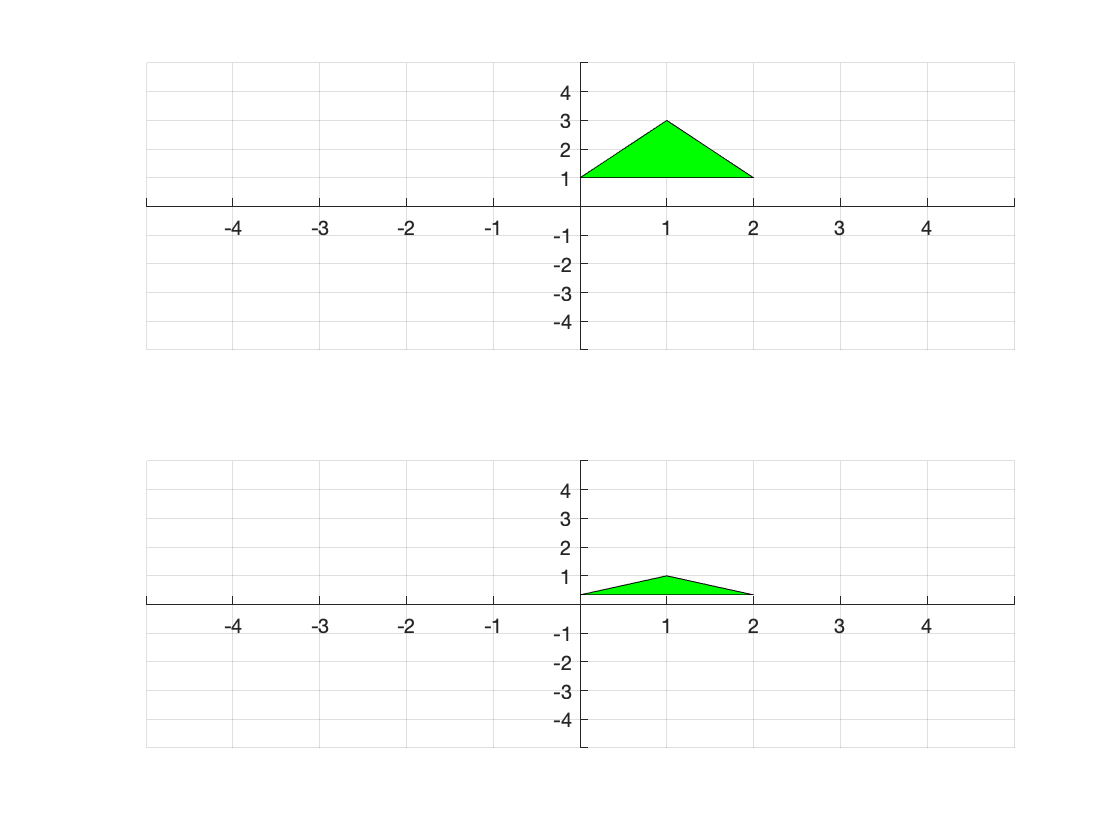

figure
x=[0 2 1];
y=[1 1 3];
subplot(2,1,1)
patch(x,y,'g')
axis([-5,5,-5,5])
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
S=[1 0;0 1/3];
pts=[x;y];
Spts=S*pts;
subplot(2,1,2)
patch(Spts(1,:),Spts(2,:),'g')
axis([-5,5,-5,5])
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Note that all of the x-values remained the same, but the y-values have been multiplied by 1/3. This is called a "contraction."

# Example #3

Use the triangle of Example #1, then double all the x-values and divide all the y-values by 3.

**Solution:** This transformation will be


$$S\left(\pmatrix{x\cr y}\right)=\pmatrix{2x\cr (1/3)y}$$


Now, inserting the standard basis vectors for $\mathbb R^2$, that is, $[S]_B=\pmatrix{S(\vec e_1) & S(\vec e_2)}$, gives us:


$$[S]_B=\pmatrix{2 & 0\cr 0 & 1/3}$$


Now, we'll simply copy our code from the previous example, and replace S with our new S.

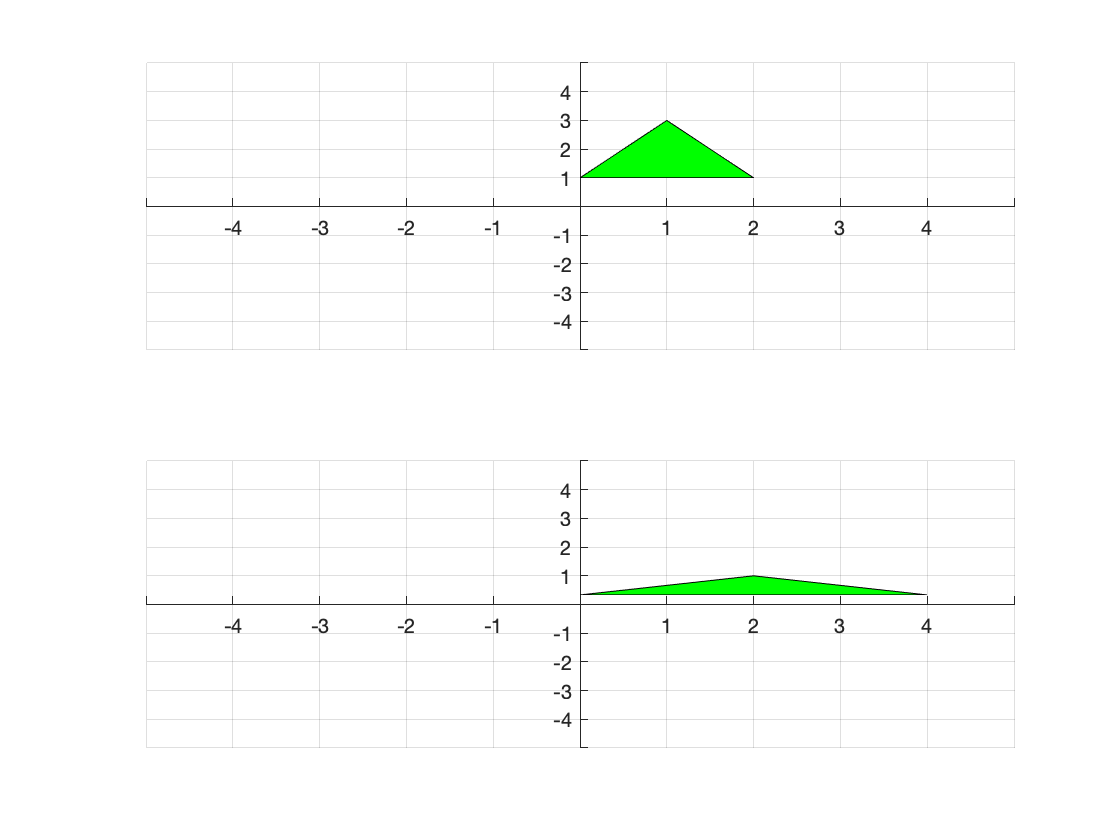

figure
x=[0 2 1];
y=[1 1 3];
subplot(2,1,1)
patch(x,y,'g')
axis([-5,5,-5,5])
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
S=[2 0;0 1/3];
pts=[x;y];
Spts=S*pts;
subplot(2,1,2)
patch(Spts(1,:),Spts(2,:),'g')
axis([-5,5,-5,5])
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

This is clear visual evidence that we have doubled all the x-values and divided the y-values by 3.

# Example #4

What is known as a horizontal shear is defined by


$$S\left(\pmatrix{x\cr y}\right)=\pmatrix{x+ky\cr y}$$


Apply a horizontal shear with $k=2$ to the triangle of Example #1.

**Solution:** The horizontal shear with $k=2$ is defined by


$$S\left(\pmatrix{x\cr y}\right)=\pmatrix{x+2y\cr y}$$


and the matrix representation relative to the standard basis is found as follows.


$$\begin{array}{rcl}
S\left(\pmatrix{1\cr 0}\right)&=&\pmatrix{1\cr 0}\\
S\left(\pmatrix{0\cr 1}\right)&=&\pmatrix{2\cr 1}\\
\end{array}$$


Therefore,


$$[S]_B=\pmatrix{1 & 2\cr 0 & 1}$$


Let's copy our code from above and replace $S$ with our new $S$.

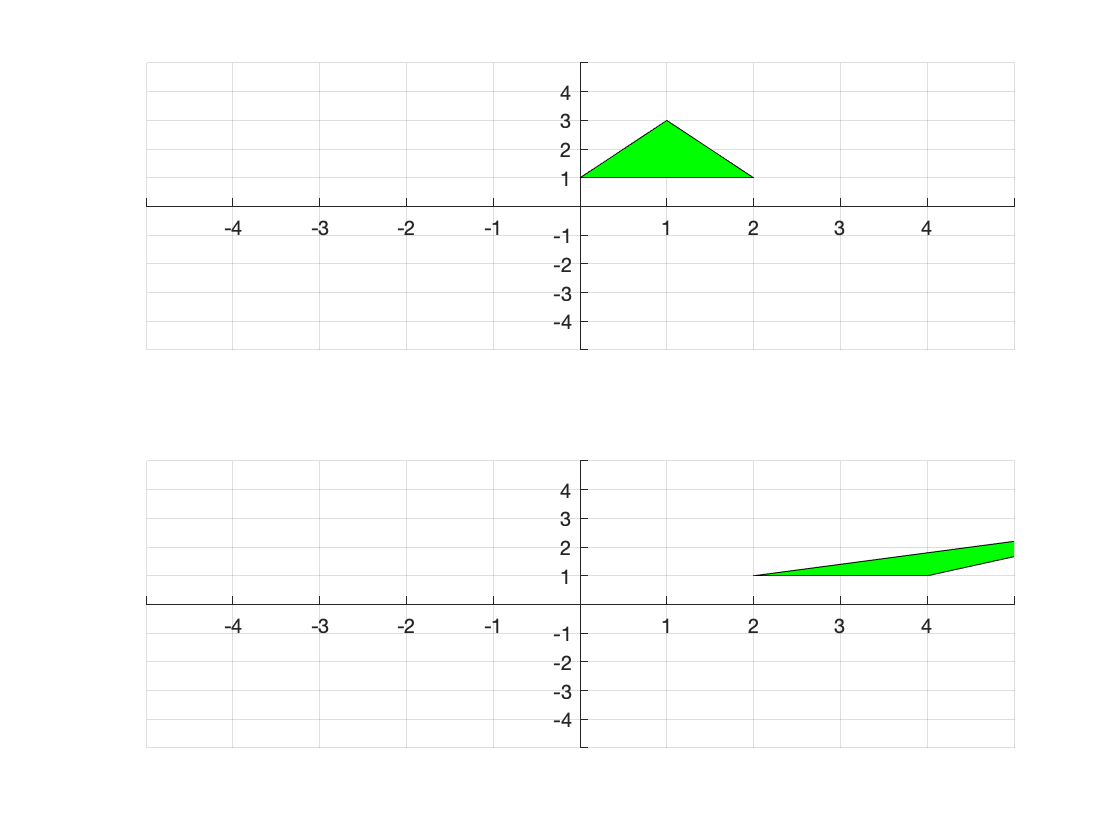

figure
x=[0 2 1];
y=[1 1 3];
subplot(2,1,1)
patch(x,y,'g')
axis([-5,5,-5,5])
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
S=[1 2;0 1];
pts=[x;y];
Spts=S*pts;
subplot(2,1,2)
patch(Spts(1,:),Spts(2,:),'g')
axis([-5,5,-5,5])
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

We'll need to adjust the axis command for our second image. We've also added an xticks(-5:8).

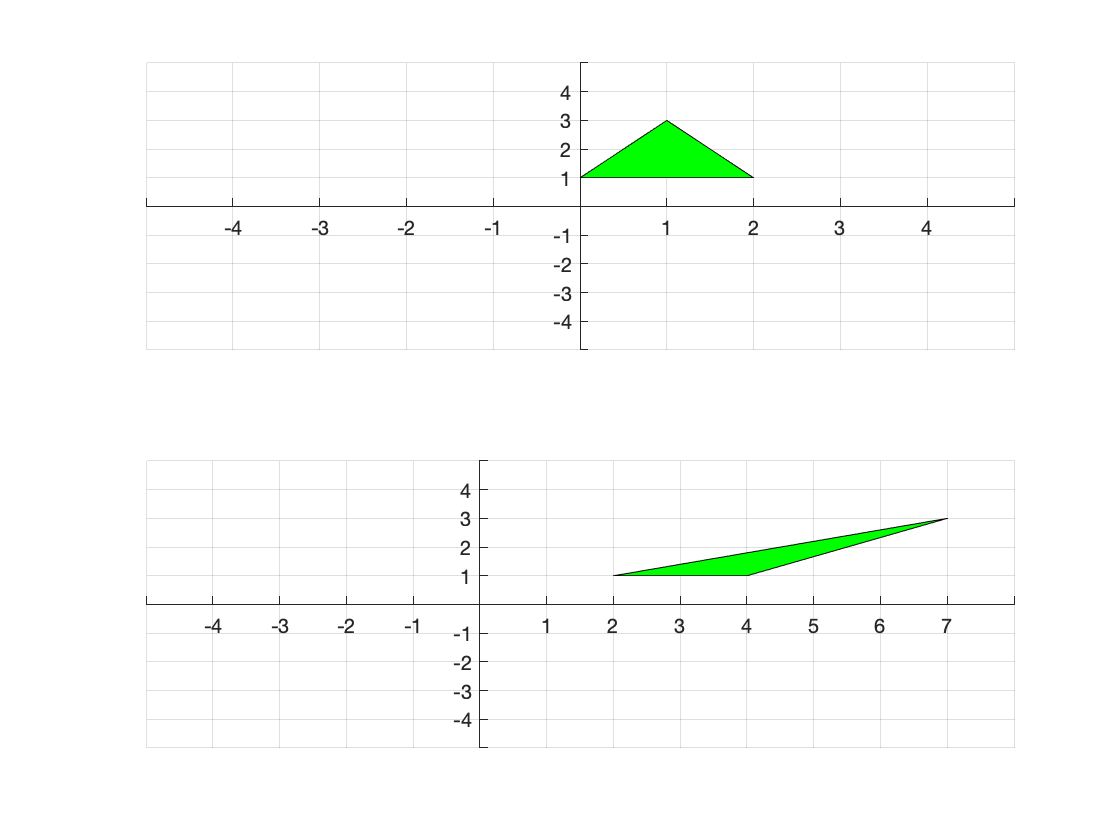

figure
x=[0 2 1];
y=[1 1 3];
subplot(2,1,1)
patch(x,y,'g')
axis([-5,5,-5,5])
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
S=[1 2;0 1];
pts=[x;y];
Spts=S*pts;
subplot(2,1,2)
patch(Spts(1,:),Spts(2,:),'g')
axis([-5,8,-5,5])
xticks(-5:8)
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Note that all the y-values remained the same; however, each x-value has changed.  This sheer transformation sent each (x,y) to (x+2y,y).

- The vertex (0,1) was sent to (0+2(1), 1), or (2,1).

- The vertex (2,1) was sent to (2+2(1), 1), or (2,1).

- The vertex (1,3) was sent to (1+2(3), 1), or (7,3).

# Example #5

Before we try our next example, let's do a little review from algebra. Consider the following image.

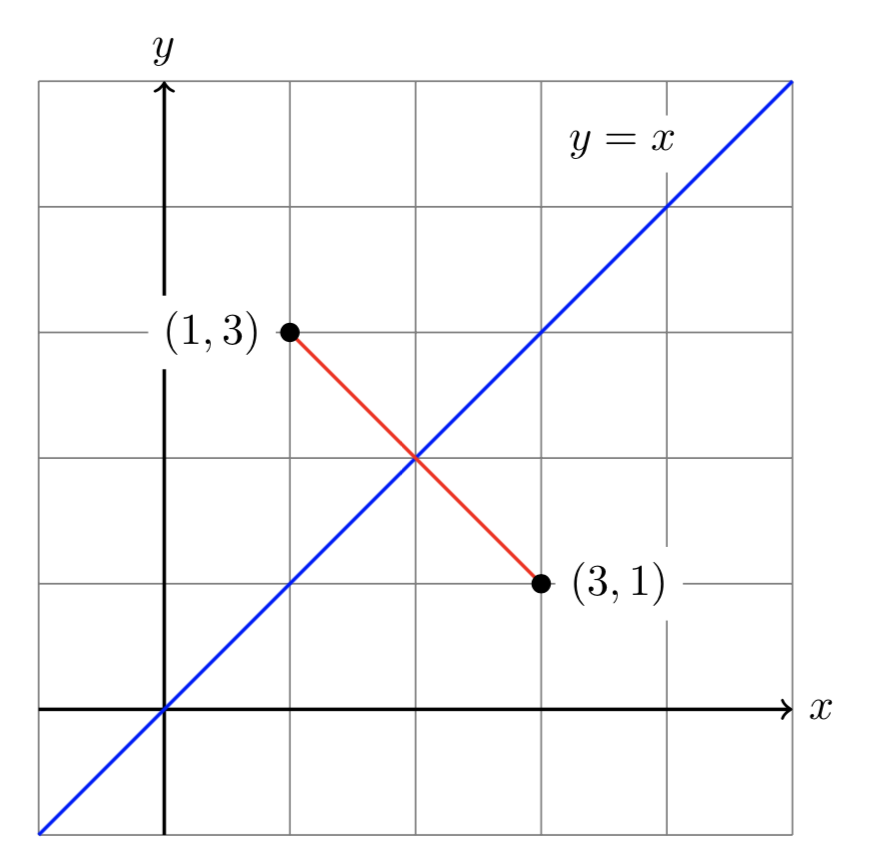

Note when the point (3,1) is reflected across the line $y=x$, its coordinates are switch to (1,3). In general, if we refelct the point $(x,y)$ across the line $y=x$, the result is the point $(y,x)$. This shows that this linear transformation will be defined by


$$S\left(\pmatrix{x\cr y}\right)=\pmatrix{y\cr x}$$


and the matrix representation relative to the standard basis is found as follows.


$$\begin{array}{rcl}
S\left(\pmatrix{1\cr 0}\right)&=&\pmatrix{0\cr 1}\\
S\left(\pmatrix{0\cr 1}\right)&=&\pmatrix{1\cr 0}\\
\end{array}$$


Therefore,


$$[S]_B=\pmatrix{0 & 1\cr 1 & 0}$$


Let's copy our code from above and replace $S$ with our new $S$. To make things a bit more clear, we added xticks and yticks and made the axis equal (which means the same scale is used on each axis.)

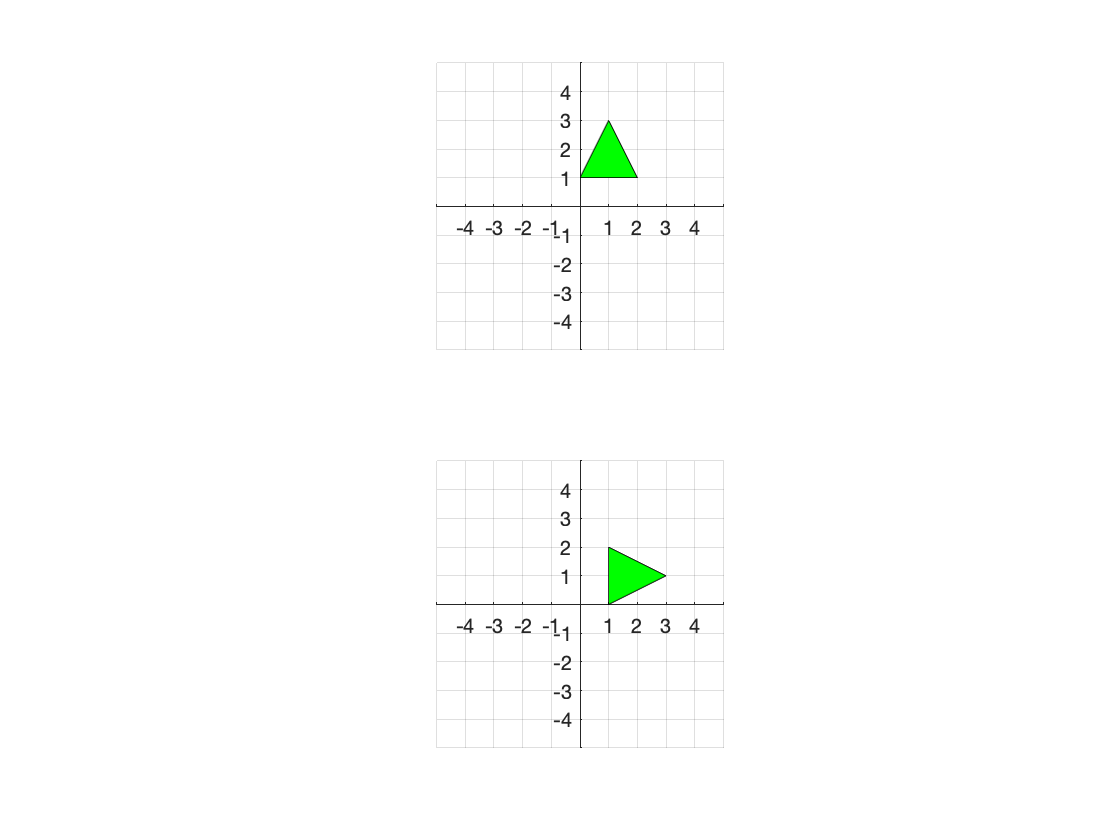

figure
x=[0 2 1];
y=[1 1 3];
subplot(2,1,1)
patch(x,y,'g')
axis equal
axis([-5,5,-5,5])
xticks(-5:5)
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
S=[0 1;1 0];
pts=[x;y];
Spts=S*pts;
subplot(2,1,2)
patch(Spts(1,:),Spts(2,:),'g')
axis equal
axis([-5,5,-5,5])
xticks(-5:5)
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

How about putting them both in the same image (each with a different color) and including the line $y=x$?

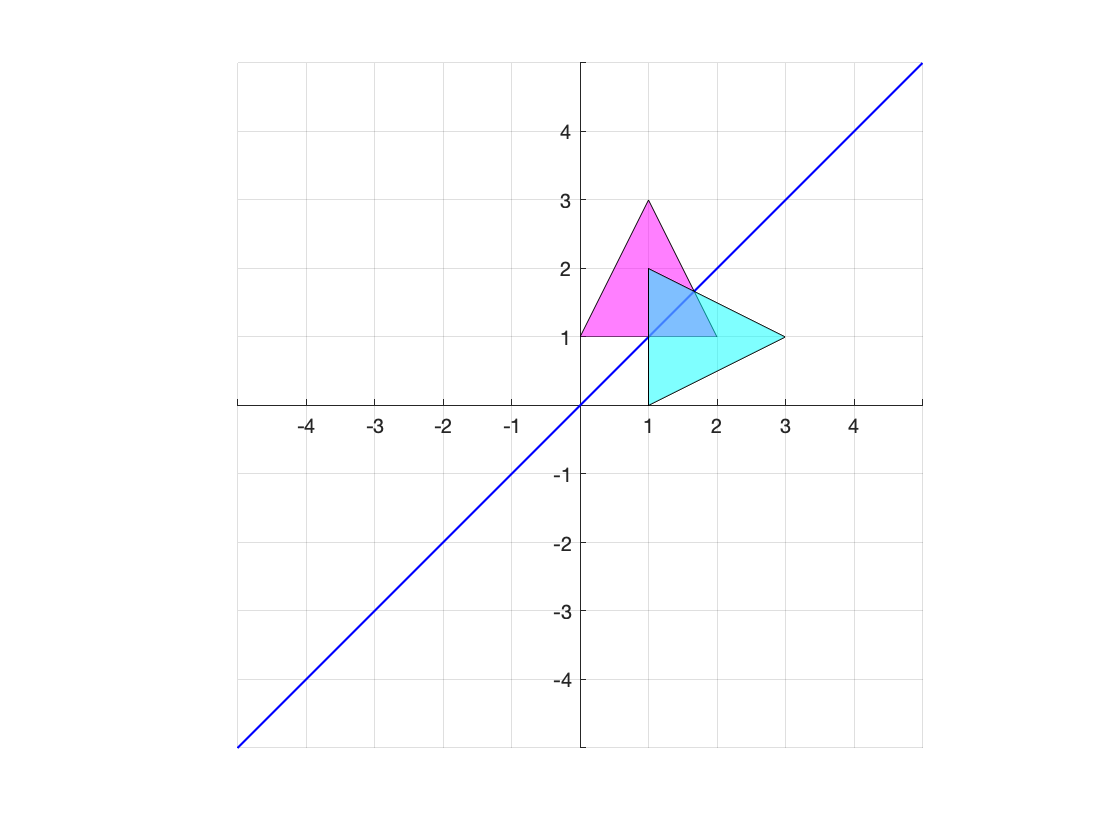

figure
line([-5,5],[-5,5],'LineWidth',1,'color','b')
x=[0 2 1];
y=[1 1 3];
patch(x,y,'m','FaceAlpha',0.5)
S=[0 1;1 0];
pts=[x;y];
Spts=S*pts;
patch(Spts(1,:),Spts(2,:),'c','FaceAlpha',0.5)
axis equal
axis([-5,5,-5,5])
xticks(-5:5)
yticks(-5:5)
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';

Ah! Much better. That definitely looks like a reflection across the line $y=x$.